# ブラケットのたわみ解析

この例では、有限要素解析（FEA）を使用して、荷重がかかった3次元機械部品を解析し、最大たわみを求める方法を示します。

## 構造解析モデルの作成

線形弾性問題を解く最初のステップは構造解析モデルの作成。

このモデルは、形状（ジオメトリ）、物性値（構造材料のプロパティ）、物体力、荷重条件、拘束条件、メッシュが含まれるコンテナです。

model = createpde('structural','static-solid');

## 形状（ジオメトリ）の読み込み

単純なブラケットモデルのSTLファイルを、 `importGeometry` を使って読み込みます。この関数により、モデルに含まれるフェース（面）、エッジ（辺）、ヴァーテックス（節点）が再構成されます。ただし、いくつかの面や辺は読み込み時にマージされる場合があるため、その数は、元となるCADモデルのそれとは異なる場合があります。

importGeometry(model,'BracketWithHole.stl');

面番号を表示しながらジオメトリを描画します。

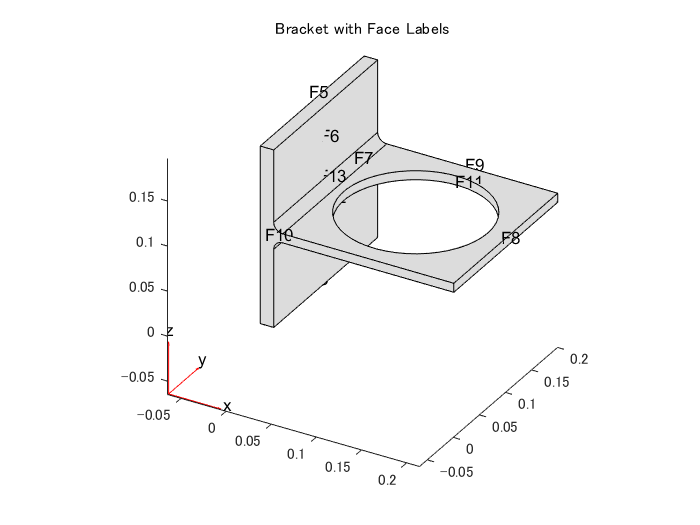

figure
pdegplot(model,'FaceLabels','on')
view(30,30);
title('Bracket with Face Labels')

## 物性値の指定

材料のヤング率とポアソン比を指定します。

structuralProperties(model,'Cell',1,'YoungsModulus',200e9, ...
                                    'PoissonsRatio',0.3);

## 拘束条件や荷重条件といった境界条件の設定

この問題では２つの境界条件を設定します。裏面（面４）を完全拘束し、表面に荷重を設定します。その他はデフォルト設定：自由境界です。

structuralBC(model,'Face',4,'Constraint','fixed');

表面である面８に、等分布荷重を - z 方向に設定します。

distributedLoad = 1e4; % Applied load in Pascals
structuralBoundaryLoad (model,'Face',8,'SurfaceTraction',[0;0;-distributedLoad]);

## メッシュの生成

二次補間関数を持つ10ノードの四面体要素を使用したメッシュを作成します。この要素タイプは、特に曲げを伴う弾性解析において、線形補間（4ノード）要素よりも大幅に精度が高くなります。

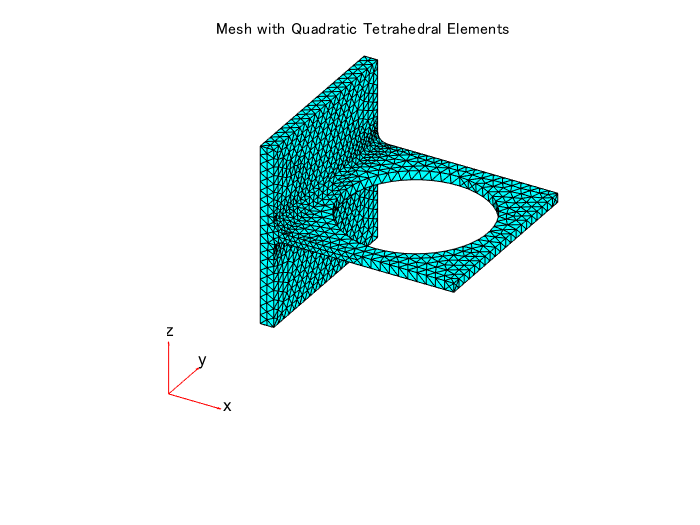

bracketThickness = 1e-2; % Thickness of horizontal plate with hole, meters
generateMesh(model,'Hmax',bracketThickness);
figure
pdeplot3D(model)
title('Mesh with Quadratic Tetrahedral Elements');

## 求解

`solve` を使って解を求めます。

result = solve(model);

## 解のチェック

Z方向の最大たわみを計算します。

minUz = min(result.Displacement.uz);
fprintf('Maximal deflection in the z-direction is %g meters.', minUz)

Maximal deflection in the z-direction is -4.48952e-05 meters.

## 変位量のプロット

Z方向のたわみが最も大きくなります。構造解析対象である部品と荷重条件が対称であるため、X方向の変位とZ方向の変位は中心線に対して対称になり、Y方向の変位は非対称になっています。

JETカラーマップを使って描画します。このカラーマップにおいて青は最低値になり、赤が最大値になります。面８に荷重がかかってるため、Z方向の変位は、この面が最小値（絶対値としては最大）になります。

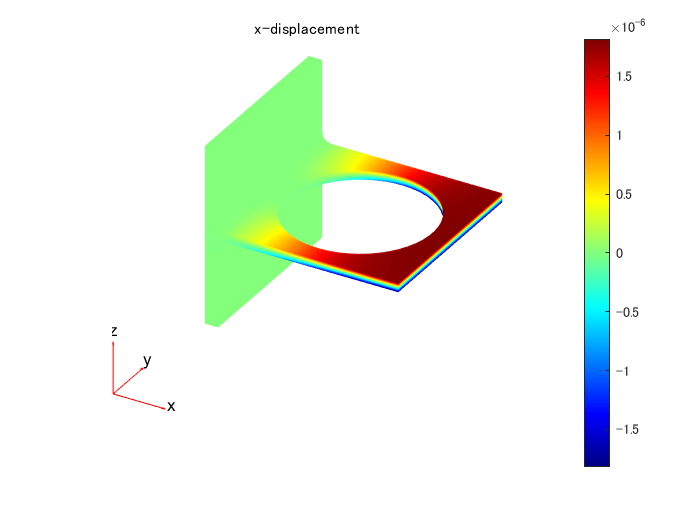

figure
pdeplot3D(model,'ColorMapData',result.Displacement.ux)
title('x-displacement')
colormap('jet')

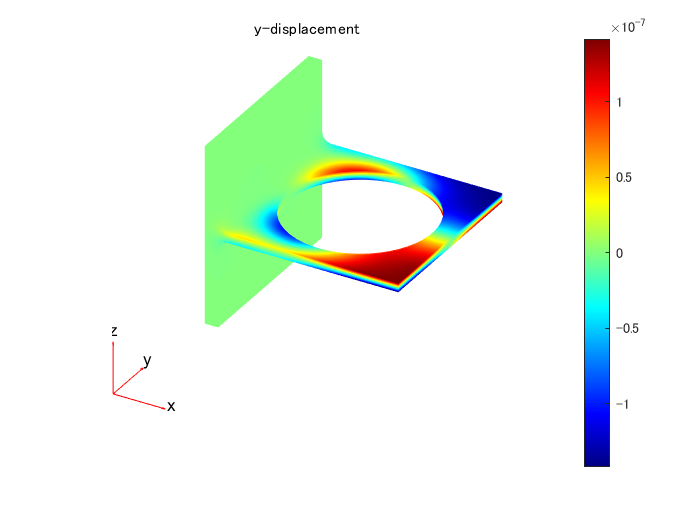


figure
pdeplot3D(model,'ColorMapData',result.Displacement.uy)
title('y-displacement')
colormap('jet')

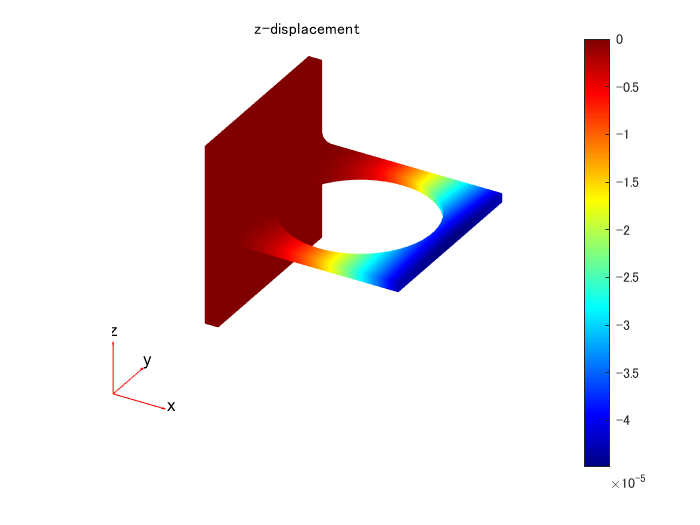


figure
pdeplot3D(model,'ColorMapData',result.Displacement.uz)
title('z-displacement')
colormap('jet')

## フォン・ミーゼス応力の描画

フォン・ミーゼス応力を節点位置に描画します。JETカラーマップを使用します。

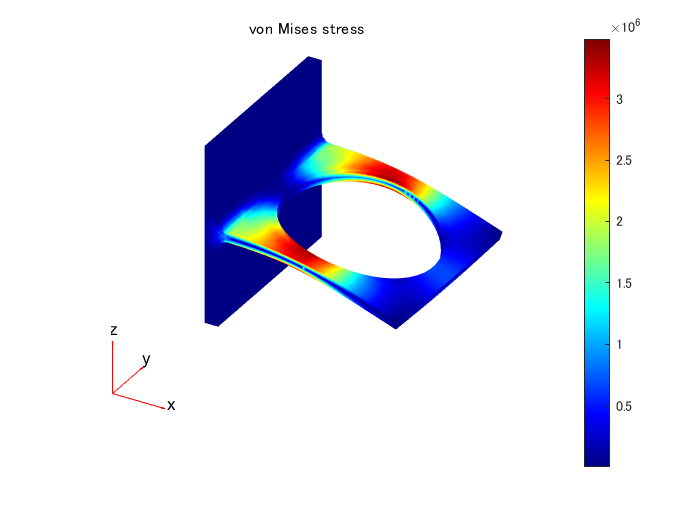

figure
pdeplot3D(model,'ColorMapData',result.VonMisesStress,'Deformation',result.Displacement,'DeformationScaleFactor',1000)
title('von Mises stress')

*Copyright 2014-2020 The MathWorks, Inc.*